           В волноводе квадратного сечения с размерами a = b = 7,2 мм, заполненном воздухом, стенки которого сделаны из материала с проводимостью $\sigma$ = (0,5·M+0,01·N)·10^7 См/м, распространяется волна типа Н11. Определить частоту поля, при которой затухание минимально, минимальное значение коэффициента затухания и диапазон частот, в пределах которого значение коэффициента затухания отличается от минимального не более чем на 20%. Показать этот диапазон на графике. При расчетах учитывать только потери в металле.

- **КОНСТАНТЫ**

c = 3e8

c = 300000000

e0 = 8.85e-12

e0 = 8.8500e-12

m0 = 1.25e-6

m0 = 1.2500e-06

- **ДАНО**

M = 5; N = 12;
a = 7.2 * 1e-3 % мм -> м

a = 0.0072

b = 7.2 * 1e-3 % мм -> м

b = 0.0072

sigma = (0.5*M + 0.011*N)*1e7

sigma = 26320000

nu = 0.1 + 1 % %

nu = 1.1000

- **НАЙТИ**

Определить частоту поля, при которой затухание минимально,

 минимальное значение коэффициента затухания и диапазон частот, в пределах которого значение коэффициента затухания отличается от минимального не более чем на 20%. 

Показать этот диапазон на графике. 

- **РЕШЕНИЕ**

Потери в волноводе 


$$\alpha =\alpha_M +\alpha_Д ,$$


где ам -коэффициент ослабления в металле и ад -коэффицент ослабления в диэлектрике. Так как средой, заполняющей волновод, является воздух, потерями в диэлектрике можно принебречь 


$$\left(\alpha_Д \longrightarrow 0\right),\Longrightarrow \alpha \approx \alpha_М \ldotp$$


Коэффицент ослабления в металле для волны типа Н11


$$\alpha_M =\frac{2R_s }{Z_0 a\sqrt{1-{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 }}\left(2{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 +{\left(1-{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 \right)} \right),$$



$$\alpha_M =\frac{2R_s }{Z_0 a\sqrt{1-{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 }}\left(1+{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 \right),$$


где


$$\lambda_{\textrm{кр}} =\frac{2\pi }{\chi }=\frac{2}{\sqrt{{\left(\frac{1}{a}\right)}^2 +{\left(\frac{1}{b}\right)}^2 }}=\frac{2}{\sqrt{{\left(\frac{1}{0,072}\right)}^2 +{\left(\frac{1}{0,072}\right)}^2 }}=0,0102\;\left\lbrack м\right\rbrack ,$$


это критическая длина волны для поля Н11,


$$\lambda =\frac{c}{f},$$


длина волны в среде волновода, где с - скорость света.


$$Z_0 =\sqrt{\frac{\mu_a }{\varepsilon_a }}=\sqrt{\frac{\mu_0 }{\varepsilon_0 }}=120\cdot \pi =377\;\left\lbrack \textrm{Ом}\right\rbrack ,$$


волновое сопротивление среды и


$$R_s =\sqrt{\frac{w\mu_a }{2\sigma }}=\sqrt{\frac{\pi f\mu_0 }{\sigma }},$$


поверхностное сопротивление металла. ???


$$\alpha_M =\frac{2\cdot \sqrt{\frac{\pi \cdot f\cdot 1,25\cdot {10}^{-6} }{2,62\cdot {10}^7 }}}{377\cdot 0,0072\cdot \sqrt{1-{\left(\frac{3\cdot {10}^8 }{0,0102\cdot f}\right)}^2 }}\left({1+\left(\frac{3\cdot {10}^8 }{0,0102\cdot f}\right)}^2 \right),$$



$$\alpha_M =\frac{2,85\cdot {10}^{-7} \cdot \sqrt{f}}{\sqrt{1-\frac{8,41\cdot {10}^{20} }{f^2 }}}\left(1+\frac{8,41\cdot {10}^{20} }{f^2 }\right)\ldotp$$


Условие максимума/минимума функции


$$\frac{d\alpha \left(f\right)}{df}=0\Longrightarrow f_{\min } =\;2,9\cdot {10}^{10} \;\left\lbrack \textrm{Гц}\right\rbrack \ldotp$$


Минимальный коэффициент ослабления 


$$\alpha \left(f_{\min } \right)=2,147\;\left\lbrack \frac{1}{м}\right\rbrack \ldotp$$


Полное затухание по мощности


$$k\left(f\right)=e^{-2\alpha \left(f\right)L} ,\mathrm{т}\ldotp \mathrm{к}\ldotp L=1\left\lbrack м\right\rbrack ,\textrm{то}\;\;k_{\max } \left(f\right)=e^{-2\alpha_{\min } \left(f\right)L} ,$$



$$k_{\max } \left(f\right)=e^{-2\cdot 2,147\cdot 1} =0,014\ldotp$$


20 % погонного затухания


$$0,8\cdot k_{\max } =0,011,$$


Диапазон частот, в пределах которого погонное затухание отличается не более чем на 20% (от 0,014 до 0,011)

lamda_krat = 2/sqrt(2*(1/b)^2)

lamda_krat = 0.0102

cla reset;
[a, f] = a_graph(b, sigma, m0, lamda_krat, 1);
a_min = find(a < (min(a) + 0.0000000000001));  % Должно быть одно число
fprintf('a_min = %1.4f|id_min = %1i|a = %1.4f|f = %1.0e', min(a), a_min, a(a_min), f(a_min));

a_min = 0.0977|id_min = 41130|a = 0.0977|f = 7e+10

plot(f(1:a_min), a(1:a_min), 'blue');
hold on; 
plot(f((a_min(end)+1):(a_min(end)+2)), a((a_min(end)+1):(a_min(end)+2)), ['o', 'black']);
plot( f((a_min(end)+2):end), a((a_min(end)+2):end), 'blue')
plot([f(a_min) f(a_min)], [0 a(a_min)], "r-", LineWidth=1);
a_max = find(a < (min(a) * nu))

a_max =        18908       18909       18910       18911       18912       18913       18914       18915       18916       18917       18918       18919       18920       18921       18922       18923       18924       18925       18926       18927       18928       18929       18930       18931       18932       18933       18934       18935       18936       18937       18938       18939       18940       18941       18942       18943       18944       18945       18946       18947       18948       18949       18950       18951       18952       18953       18954       18955       18956       18957


fprintf('a_max1 = %1.4f|a_max2 = %1.4f', a(a_max(1)), a(a_max(end)));

a_max1 = 0.1075|a_max2 = 0.1075

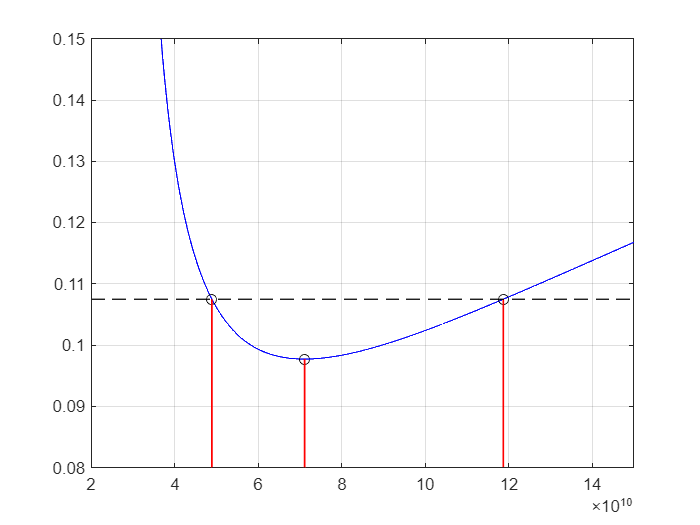

plot(f((a_max(1)+1):(a_max(1)+2)), a((a_max(1)+1):(a_max(1)+2)), ['o', 'black']);
plot(f((a_max(end)+1):(a_max(end)+2)), a((a_max(end)+1):(a_max(end)+2)), ['o', 'black']);
plot([f(a_max(1)) f(a_max(1))], [0 a(a_max(1))], ['-', 'red'], LineWidth=1);
plot([f(a_max(end)) f(a_max(end))], [0 a(a_max(end))], ['-', 'red'], LineWidth=1);
% plot([f(a_max(1)) f(a_max(end))], [a(a_max(1)) a(a_max(end))], ['--', 'black'], LineWidth=0.7);
plot([0 f(470001)], [a(a_max(1)) a(a_max(1))], ['--', 'black'], LineWidth=0.7);
ylim([0.08 0.15]);
xlim([2e10 1.5e11]);
grid on;
xlabel("");

% plot([0 a(a_min)], [f(a_min) f(a_min)], "--", LineWidth=6);



$$R_s =\sqrt{\frac{w\mu_a }{2\sigma }}=\sqrt{\frac{\pi f\mu_0 }{\sigma }},$$



$$\alpha_M =\frac{2R_s }{Z_0 a\sqrt{1-{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 }}\left(1+{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 \right),$$


function [a, f] = a_graph(b, sigma, m0, lamda_krat, n)
    %
    c = 3e8;
%     h = 3e10:1e6:5e11
    %
    f = linspace(3e10, 5e11, 470001);
    a = zeros(1, 470001); 
    %
    Z0 = 377;
    for v = 3e10:1e6:5e11
        lamda = c/v;
        l_na_l_in_2 = (lamda/lamda_krat)^2;
        Rs = sqrt((pi*v*m0)/sigma);
        a(n) = ((2 * Rs)/(Z0 * b * sqrt(1 - l_na_l_in_2)))*(1 + l_na_l_in_2);
        n = n + 1;
    end 
end